# Fit of baseline and phase corrected data from 2021-06-28

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\20210628';
load([Opt.LFolder, '\cwEDMR_2021_06_28.mat']);
[~, ncw] = size(x);

#### Fit

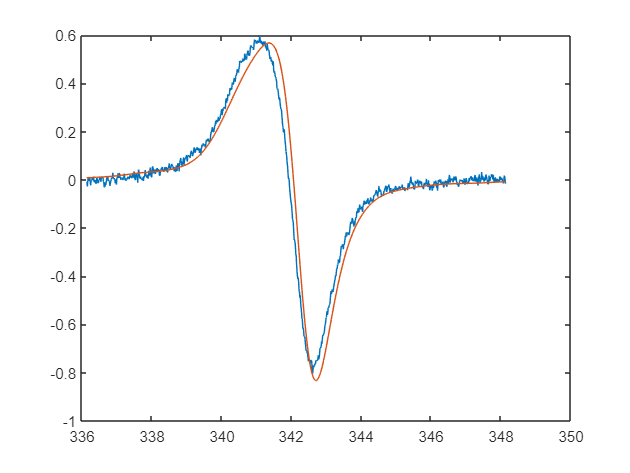

SysDb = struct(g = [2.0079 2.0061 2.0034], ...
    gStrain = [0.0054 0.0022 0.0018], ...
    lw = [0. 1.4], ...
    Nucs = 'Si', A = [151 269]);
VaryDb = struct( ...
    lw = SysDb.lw);

SysV = struct(g = 2.01, ...
    gStrain = 0.0098, ...
    lw = [.0 1], ...
    weight = 0.5);
VaryV = struct( ...
    lw = SysV.lw, ...
    weight = SysV.weight);

SysC = struct(g = 2.0044, ...
    lw = [3. 0.], ...
    weight = 0.5);
VaryC = struct(...
    lw = SysC.lw);
    % weight = SysC.weight);

SysTE = struct(g = 2.0077, ...
    gStrain = 0.0036, ...
    lw = [30 0], ...
    weight = 1);
VaryTE = struct(...
    lw = SysTE.lw, ...
    weight = SysC.weight);

Exp.mwFreq = 9.6055875; % GHz

Sys = {SysDb, SysV};
Vary = {VaryDb, VaryV};

FitOpt.PrintLevel = 0;
FitOpt.Baseline = 2;    % Quadratic baseline, residual of the previous bl correction

icw = 1;
Exp.Range = [min(x(:, icw)) max(x(:, icw))];
Exp.mwFreq = cwStruct(icw).Params(1).MWFQ*1e-9;
figure()
plot(x(:, icw), y(:, icw))
hold on
plot(x(:, icw), scaleY(pepper(Sys, Exp), y(:, icw)))

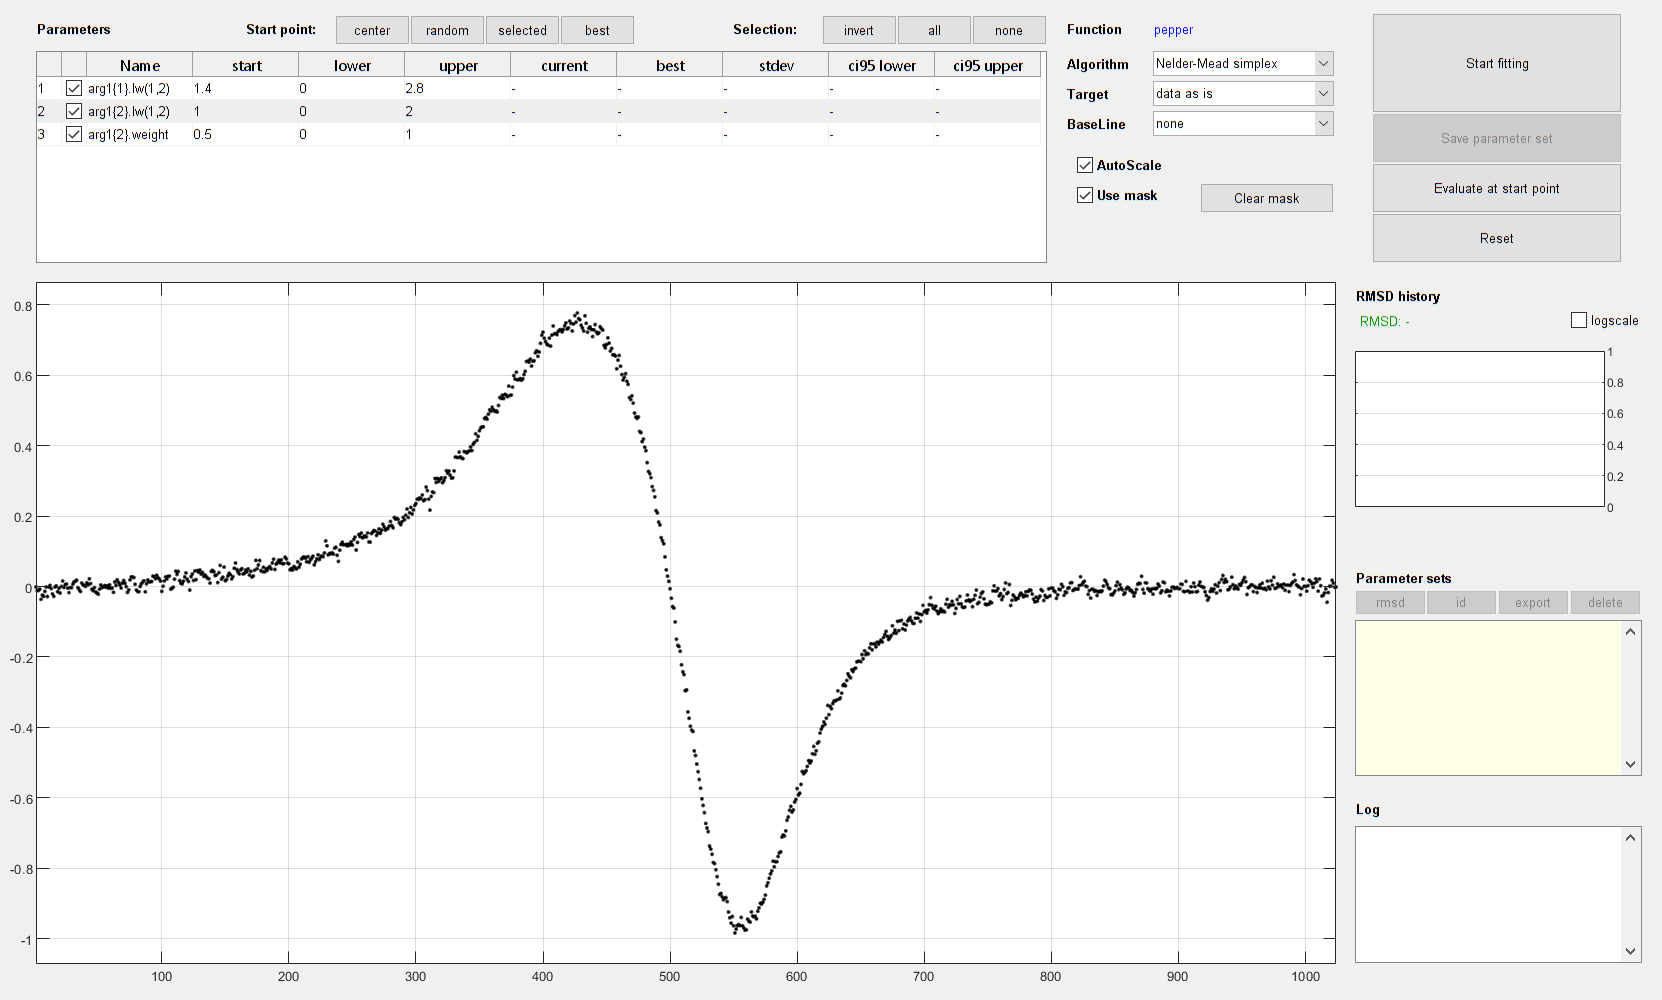

icw = 2;
Exp.Range = [min(x(:, icw)) max(x(:, icw))];
Exp.mwFreq = cwStruct(icw).Params(1).MWFQ*1e-9;
esfit(y(:, icw), @pepper, {Sys, Exp}, {Vary})

wbar = waitbar(0, 'Performing least-square fitting', ...
    'Name', 'esfit in progress');
for icw = 1:ncw
    x_ = x(:, icw); y_ = y(:, icw);
    Exp.Range = [min(x_) max(x_)];
    Exp.mwFreq = cwStruct(icw).Params(1).MWFQ*1e-9;
    Fit_ = esfit(y_, @pepper, {Sys, Exp}, {Vary}, FitOpt);
    
    % Simulate components separately.
    bestSysDb_ = Fit_.argsfit{1, 1}{1, 1};
    bestSysV_ = Fit_.argsfit{1, 1}{1, 2};
    Exp_ = Fit_.argsfit{1, 2};
    Fit_.DbFit = pepper(bestSysDb_, Exp_)*Fit_.scale;
    Fit_.VFit = pepper(bestSysV_, Exp_)*Fit_.scale;

    % Store in structure
    if icw == 1
        Fit = repmat(Fit_, 1, ncw);
    else
        Fit(icw) = Fit_;
    end
    waitbar(icw/ncw, wbar)
end

-- esfit ------------------------------------------------
Data size:                [1024, 1]
Model function name:      pepper
Number of fit parameters: 3
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 3 active parameters...
iteration   1: value 4.49239e-02   edge 1.00000e-01   initial simplex
iteration   2: value 2.91787e-02   edge 3.33333e-01   expansion
iteration   3: value 2.91787e-02   edge 3.33333e-01   reflection
iteration   4: value 2.91787e-02   edge 3.33333e-01   contraction inside
iteration   5: value 2.91787e-02   edge 2.56173e-01   reflection
iteration   6: value 2.91787e-02   edge 1.52578e-01   contraction inside
iteration   7: value 2.21134e-02   edge 2.80785e-01   expansion
iteration   8: value 2.21134e-02   edge 2.80785e-01   contraction inside
iteration   9: value 2.21134e-02   edge 2.72463e-01   reflection
iter

** Spectrum exceeds sweep range. Artifacts at upper limit possible.


-- esfit ------------------------------------------------
Data size:                [1024, 1]
Model function name:      pepper
Number of fit parameters: 3
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 3 active parameters...
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
iteration   1: value 4.68162e-02   edge 1.00000e-01   initial simplex
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
iteration   2: value 4.29458e-02   edge 2.00000e-01   reflection
** Spectrum exceeds sweep range. Artifacts at upper limit possible.
** Sp

** Spectrum exceeds sweep range. Artifacts at upper limit possible.


delete(wbar)

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
saveStr = input('Export data to .mat file? y/n\n', 's');
if strcmp(saveStr, 'y')
    save([Opt.SFolder, '\fit_2021_06_28'], 'x', 'y', 'cwStruct', 'Fit');
    % exportgraphics(gcf, [Opt.SFolder, '/2022-06-17 cwEDMR forward bias.png'])
else
    disp('Data not exported')
end

## Figure 

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
load([Opt.LFolder, '\fit_2021_06_28']);
[~, ncw] = size(x);

grayC = '#b2beb5';

(1.1 148), (1.2 217), (1.25 256), (1.3 294)

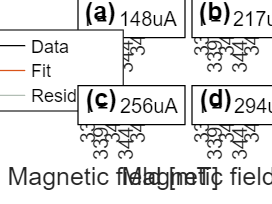

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    nexttile
    h(1) = plot(x(:, icw), y(:, icw), 'Color', [0 0 0]);
    hold on
    h(2) = plot(x(:, icw), Fit(icw).fit);
    h(3) = plot(x(:, icw), y(:, icw) - Fit(icw).fit, 'Color', grayC);
    
    set(gca,'Children',[h(2) h(1) h(3)]) % [top, middle, bottom]
    set(gca, "Layer", "top")

    xticks(337:2.5:347); yticks(-1:0.5:1);
    xlim(setAxLim(x(:, icw), 0)); ylim(setAxLim(y(:, icw), 0.1));

    if icw == ncw - 3 || icw == ncw - 1
        ylabel('EDMR signal [a. u.]', 'FontSize', 10)
    end
    if icw > ncw - 2
        xlabel('Magnetic field [mT]', 'FontSize', 10)
    end

    % title(cw(icw).Title)
    annStr = {sprintf('I = %s', cwStruct(icw).Title(end-5:end))};
    text(0.05, 0.15, annStr, 'Units', 'normalized', ...
        'FontSize', 8, ...
        'BackgroundColor', 'white', ...
        'EdgeColor', 'black');
end
annotateSubplotId(tL)
legendFirstTile(tL, ["Data", "Fit", "Residuals"], [h(1) h(2) h(3)]);

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(gcf, Opt.SFolder, '/2021-06-28 cwEDMR fit', '.png', 'residuals')

Graphics not exported


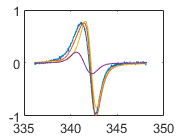

SysDb = struct(g = [2.0079 2.0061 2.0034], ...
    gStrain = [0.0054 0.0022 0.0018], ...
    lw = [0. 1.5], ...
    Nucs = 'Si', A = [151 269]);

SysV = struct(g = 2.01, ...
    gStrain = 0.0098, ...
    lw = [.0 0.75], ...
    weight = 0.25);

SysC = struct(g = 2.0044, ...
    lw = [5. 0.], ...
    weight = 0.4);

Exp.mwFreq = 9.6055875; % GHz

Sys = {SysDb, SysV, SysC};

icw = 2;
Exp.Range = [min(x(:, icw)) max(x(:, icw))];
Exp.mwFreq = cwStruct(icw).Params(1).MWFQ*1e-9;
Total = pepper({SysDb, SysV}, Exp);
Db = pepper(SysDb, Exp);
V = pepper(SysV, Exp);
% C = pepper(SysC, Exp);
[Total, F] = scaleY(Total, y(:, icw));
figure()
plot(x(:, icw), y(:, icw))
hold on
plot(x(:, icw), Total)
plot(x(:, icw), F*Db)
plot(x(:, icw), F*V)

% plot(x(:, icw), F*C)


## Figure fit components

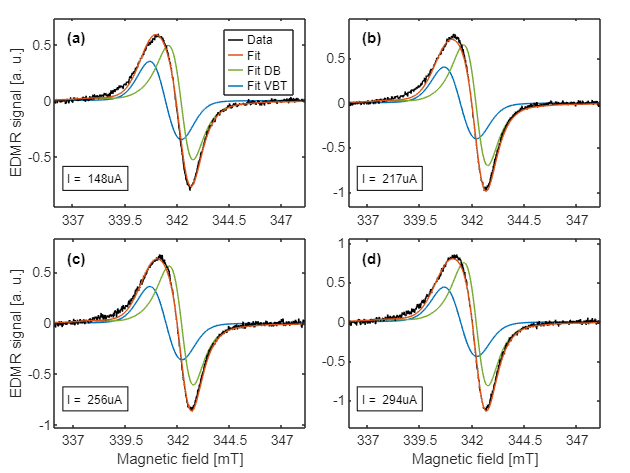

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
load([Opt.LFolder, '\fit_2021_06_28']);
[~, ncw] = size(x);

grayC = '#b2beb5';greenC = '#77AC30';
firstC = '#0072BD';
figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    ax(icw) =nexttile;
    x_ = x(:, icw); y_ = y(:, icw);
    h(1) = plot(x_, y_, 'Color', [0 0 0]);
    hold on
    h(2) = plot(x_, Fit(icw).fit);
    h(3) = plot(x_, Fit(icw).DbFit, 'Color', greenC);
    h(4) = plot(x_, Fit(icw).VFit, 'Color', firstC);

    set(gca,'Children',[h(2) h(1) h(3) h(4)]) % [top, middle, bottom]
    set(gca, "Layer", "top")

    xticks(337:2.5:347); yticks(-1:0.5:1);
    xlim(setAxLim(x(:, icw), 0)); ylim(setAxLim(y(:, icw), 0.1));

    if icw == ncw - 3 || icw == ncw - 1
        ylabel('EDMR signal [a. u.]', 'FontSize', 10)
    end
    if icw > ncw - 2
        xlabel('Magnetic field [mT]', 'FontSize', 10)
    end

    annStr = {sprintf('I = %s', cwStruct(icw).Title(end-5:end))};
    text(0.05, 0.15, annStr, 'Units', 'normalized', ...
        'FontSize', 8, ...
        'BackgroundColor', 'white', ...
        'EdgeColor', 'black'); 
end
lgd = legendFirstTile(tL, {'Data', 'Fit', 'Fit DB', 'Fit VBT'}, h);
lgd.NumColumns = 1;
annotateSubplotId(tL)


exportStr = input('Export graphics with fit components? y/n\n', 's');
if strcmp(exportStr, 'y')
    Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
    exportgraphics(gcf, [Opt.SFolder, '/2021-06-28 cwEDMR fit components.png'])
else
    disp('Graphics not exported')
end

Graphics not exported


figure()
tL = tiledlayout('flow');
nexttile;
for icw = 2:2
    Idc_ = str2double(cwStruct(icw).Title(end-4:end-2))*1e-6; % A
    conversion = 1/15e4*1e-3/Idc_;
    x_ = x(:, icw); y_ = y(:, icw);
    h(1) = plot(x_, y_*conversion, 'Color', [0 0 0]);
    hold on
    h(2) = plot(x_, Fit(icw).fit*conversion);
    h(3) = plot(x_, Fit(icw).DbFit*conversion, 'Color', greenC);
    h(4) = plot(x_, Fit(icw).VFit*conversion, 'Color', firstC);
    h(5) = xline(mhz2mt(9.6056*1000, 2.0055), '--', 'Color', greenC);
    h(6) = xline(mhz2mt(9.6056*1000, 2.01), '--', 'Color', firstC);
    h(7) = yline(0, 'Color', grayC);
    set(gca,'Children',[h(5) h(6) h(2) h(1) h(3) h(4) h(7)]) % [top, middle, bottom]
    set(gca, "Layer", "top")

    Label3 = "g = 2.0055";
text(0.525, 0.65, Label3, 'Units', 'normalized', ...
    'FontSize', 13);
Label4 = "g = 2.01";
text(0.275, 0.1, Label4, 'Units', 'normalized', ...
    'FontSize', 13);
labelAxesFig(tL, "Magnetic Field [mT]", "EDMR signal [a.u.]")

    xticks(337:2.5:347); yticks((-3:1.5:3)*1e-5);
    xlim(setAxLim(x(:, icw), 0)); ylim(setAxLim(y_*conversion, 0.15));
end
lgd = legendFirstTile(tL, {'Data', 'Fit', 'Fit DB', 'Fit VBT'}, h);

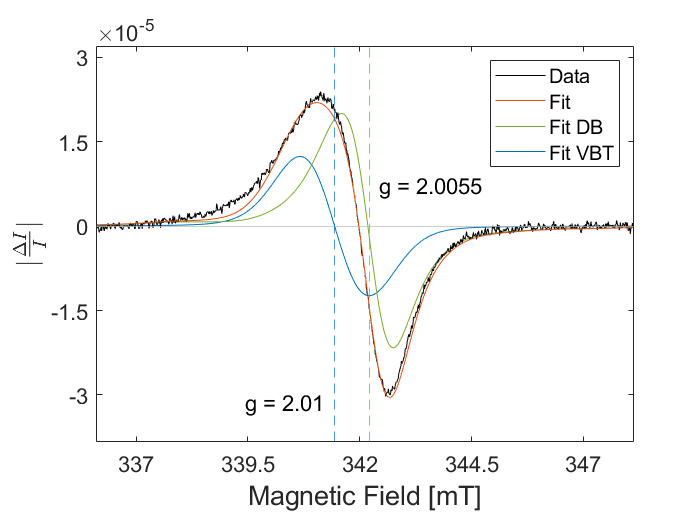

lgd.Location = "northeast";

legendFirstTile(tL);
labelAxesFig(tL, "Magnetic Field [mT]", '$| \frac{\Delta I}{I} |$')
exportFig(gcf, Opt.SFolder, '_cwEDMR fixed g Elexsys Vbias 1p2', '.png')

## SNR and dI/I pp

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
load([Opt.LFolder, '\fit_2021_06_28']);
[~, ncw] = size(x);

icw = 2;
Idc_ = str2double(cwStruct(icw).Title(end-4:end-2))*1e-6; % A
conversion = 1/15e4*1e-3/Idc_;
DeltaIoverIpp = getPeakToPeakAmp(x(:, icw), Fit(icw).fit*conversion)

DeltaIoverIpp = 5.2376e-05

SNR = getSNR(x(:, icw), y(:, icw), [0, 337; 346, 400])

SNR = 134.0805

#### "DeltaI"/I is not constant

Idc = [148 217 256 294]; % uA
figure('Visible', 'off')
hold on
for icw = 1:ncw
    plot(x(:, icw), y(:, icw)/Idc(icw))
end

## ppAmp vs Vbias

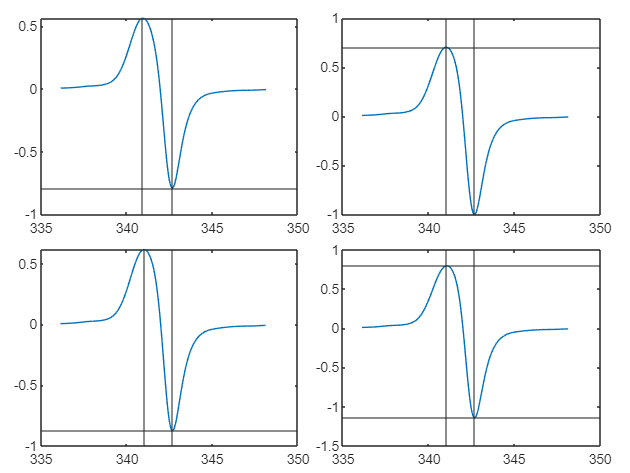

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
load([Opt.LFolder, '\fit_2021_06_28']);
[~, ncw] = size(x);

[ppAmp, yMax, yMin, xMax, xMin] = deal(zeros(1, ncw));

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    x_ = x(:, icw); y_ = y(:, icw);
    yFit_ = Fit(icw).fit; yDb_ = Fit(icw).DbFit; yV_ = Fit(icw).VFit;
    [ppAmp(icw), yMax(icw), yMin(icw), xMax(icw), xMin(icw)] = getPeakToPeakAmp(x_, yFit_);
    
    nexttile
    plot(x_, yFit_)
    hold on
    yline(yMax(icw)); yline(yMin(icw));
    xline(xMax(icw)); xline(xMin(icw));
end

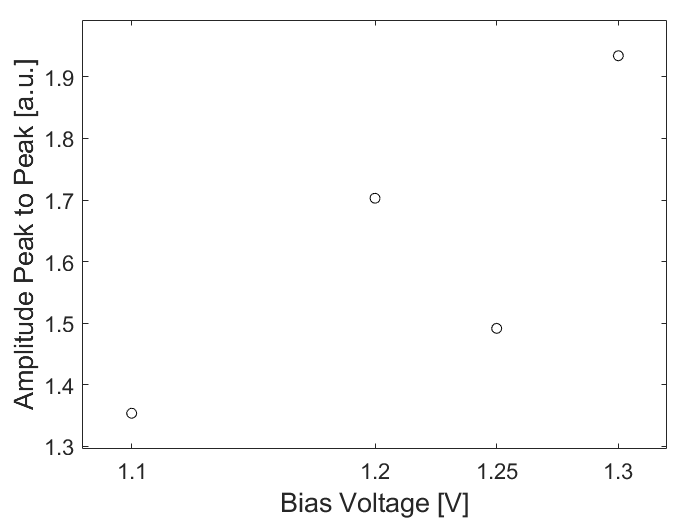

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');

ax = nexttile(1);
Vbias = [1.1, 1.2, 1.25, 1.3]; ppAmpCut = ppAmp;
h(1) = plot(Vbias, ppAmpCut, 'o', 'Color', 'black');


xticks(Vbias); 
xlim(setAxLim(Vbias, 0.1)); ylim(setAxLim(ppAmpCut, 0.1));

labelAxesFig(tL, "Bias Voltage [V]", "Amplitude Peak to Peak [a.u.]")

exportFig(gcf, Opt.SFolder, "_ppAmp elexsys", "pdf");

Graphics not exported


exportFig(gcf, Opt.SFolder, "_ppAmp elexsys", "png");

Graphics not exported


Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
load([Opt.LFolder, '\fit_2021_06_28']);
[~, ncw] = size(x);
icw = 1;
x_ = x(:, icw); y_ = y(:, icw);
yFit_ = Fit(icw).fit; yDb_ = Fit(icw).DbFit; yV_ = Fit(icw).VFit;
SNR = getSNR(x_, y_, [335, 336.5; 347.5 350])

SNR = 128.6976

getPeakToPeakAmp(x_, yFit_)

ans = 1.3539

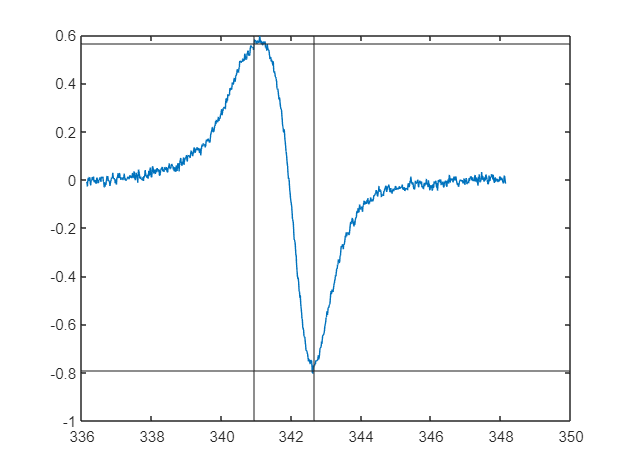

figure()
for icw = 1:1
    x_ = x(:, icw); y_ = y(:, icw);
    yFit_ = Fit(icw).fit; yDb_ = Fit(icw).DbFit; yV_ = Fit(icw).VFit;
    [ppAmp(icw), yMax(icw), yMin(icw), xMax(icw), xMin(icw)] = getPeakToPeakAmp(x_, yFit_);
    
    nexttile
    plot(x_, y_)
    hold on
    yline(yMax(icw)); yline(yMin(icw));
    xline(xMax(icw)); xline(xMin(icw));
end